clear

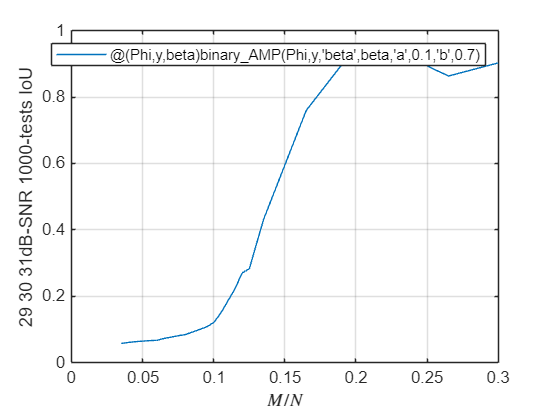

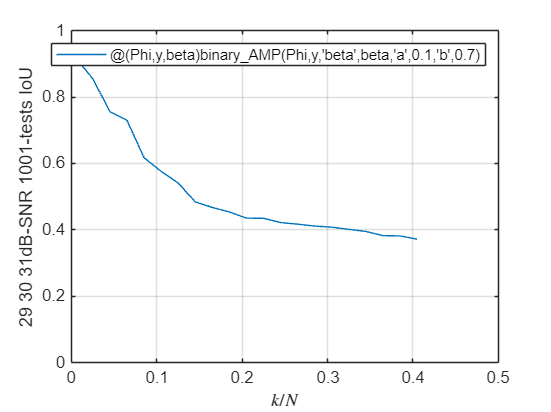

files = dir('data\');
files = files(~[files.isdir]);
[~,I] = sort({files.name});
files = files(I);


h1 = figure; hold on; xlabel('$M/N$', 'Interpreter','latex');
h2 = figure; hold on; xlabel('$k/N$', 'Interpreter','latex');

for i = 1:length(files)
    load(fullfile(files(i).folder, files(i).name))

    colName = "InfdB-SNR 1000-tests IoU";
    figure(h1); plotVaryingM(tbl, colName, algName)
    ylabel(colName)

    colName = "InfdB-SNR 1001-tests IoU";
    figure(h2); plotVaryingk(tbl, colName, algName)
    ylabel(colName)
end

for h = [h1 h2]
    figure(h)
    box on; grid on;
    legend('Interpreter','none')
    ylim([0 1])
    label = get(gca,'YLabel').String;
    if contains(label,"RED") || contains(label,"RMD")
        ylim([1e-3 Inf])
        set(gca, 'YScale','log')
    end
end

function plotVaryingM(tbl, colName, algName)

tbl = convertvars(tbl, 1:3, "double");
N = mode(tbl.N);
k = mode(tbl.k);
mask = (tbl.N == N) & (tbl.k == k) & ~isnan(tbl.(colName));
M_over_N = tbl.M(mask) / N;
data = tbl.(colName)(mask);
[M_over_N, I] = sort(M_over_N);
data = data(I);
plot(M_over_N, data, 'DisplayName',algName)

end

function plotVaryingk(tbl, colName, algName)

tbl = convertvars(tbl, 1:3, "double");
N = mode(tbl.N);
M = mode(tbl.M);
mask = (tbl.N == N) & (tbl.M == M) & ~isnan(tbl.(colName));
k_over_N = tbl.k(mask) / N;
data = tbl.(colName)(mask);
[k_over_N, I] = sort(k_over_N);
data = data(I);
plot(k_over_N, data, 'DisplayName',algName)

end